## DoptFractPoly Demonstration

This document demonstrates the use of the DoptFracPoly function to find locally D-optimal designs for fractional polynomials for logistic regression.

Start with a standard polynomial $1 + x + x^2$. We need to give the nominal coefficient values, the powers on x, the number of design points, and the design interval. We also need to specify which algorithm from PlatEMO to use.

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.09s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.12s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.19s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.23s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.26s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.29s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.35s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.38s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.41s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.44s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.47s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

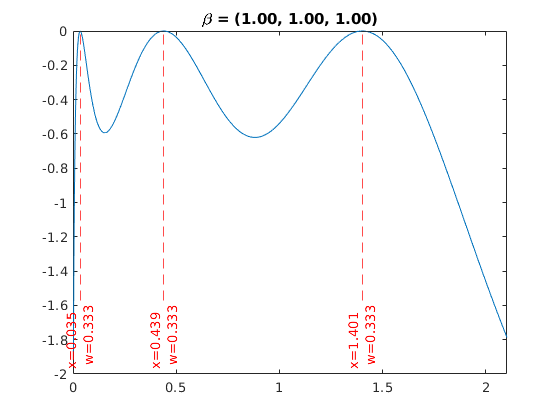

beta = [1, 1, 1];
powers = [1, 2];
pts = 3;
int = [0, Inf];
sens = true; % compute and plot sensitivity function
algo = {@GA, 100000, 1000, 1, 20, 1, 20};

[obj, xi] = DoptFracPoly(beta, powers, pts, sens, algo, int);

The function returns the objective value obtained and the optimal design points with the corresponding weights. The sensitivity function will also be plotted.

Now suppose we want to find the optimal design for $1 + x^{-1} + \sqrt{x}$. We can do this by changing the powers vector.

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.11s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.14s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.17s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.24s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.27s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.30s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.33s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.39s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.42s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.45s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

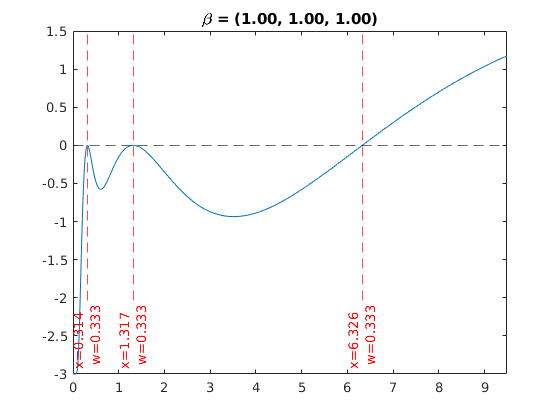

powers = [-1, 0.5];
[obj, xi] = DoptFracPoly(beta, powers, pts, sens, algo, int);

Note that the algorithm does not find the optimal design as indicated by the sensitivity plot. It seems that some designs have an unbounded 3rd point that causes some issues in finding the optimal design. This problem may be solved by specifying an upper bound for $x$. This approach should be applicable in most situations.

GA on 1-objective 6-variable UserProblem (  1.00%), 0.05s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.09s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.13s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.23s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.26s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.29s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.35s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.38s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.41s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.44s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.47s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

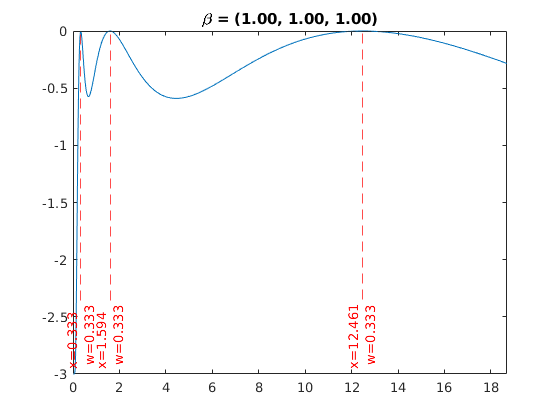

int = [0, 20];
[obj, xi] = DoptFracPoly(beta, powers, pts, sens, algo, int);

## Examples of Designs

In their original paper, Royston and Altman give two applied examples of logistic regression using fractional polynomials. In both cases, they find the best values of the powers so that the model fits the data optimally. The authors do not share the final regression coefficients. Therefore, we will find optimal designs for the two sets of powers and experiement with different values for the regression coeffficients.

### In Vitro Fertilization example, p = (-1, 1)

powers = [-1, 1];

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.11s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.14s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.17s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.23s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.26s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.29s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.32s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.39s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.43s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.47s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

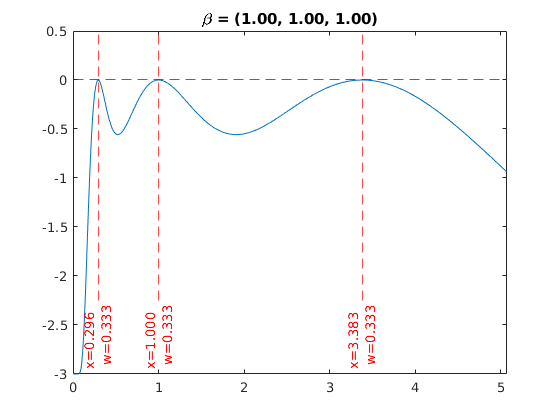

% simple coef
beta = [1,1,1];
pts = 3;
sens = true;
int = [0, 100];
[obj, xi] = DoptFracPoly(beta, powers, pts, sens, algo, int);

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.11s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.14s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.17s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.21s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.24s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.27s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.30s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.33s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.39s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.42s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.45s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

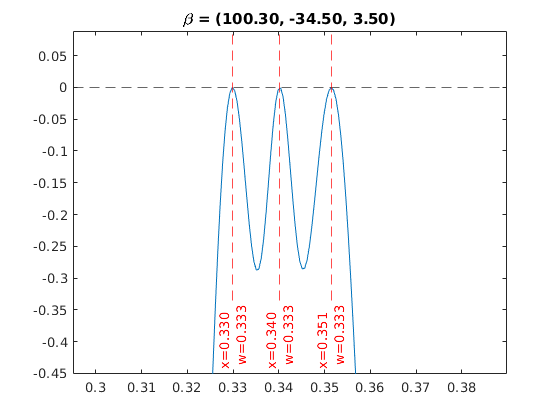

% more complicated case
beta = [100.3, -34.5, 3.5];
[obj, xi] = DoptFracPoly(beta, powers, pts, sens, algo, int);

### Myelomatosis example, p = (-2, 3)

The model used for this example from Royston and Altman included other covariates, but it is still interesting to look at the fractional polynomial in isolation.

powers = [-2, 3];

GA on 1-objective 6-variable UserProblem (  1.00%), 0.05s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.09s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.14s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.17s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.24s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.27s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.30s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.33s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.40s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.43s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.46s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.49s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

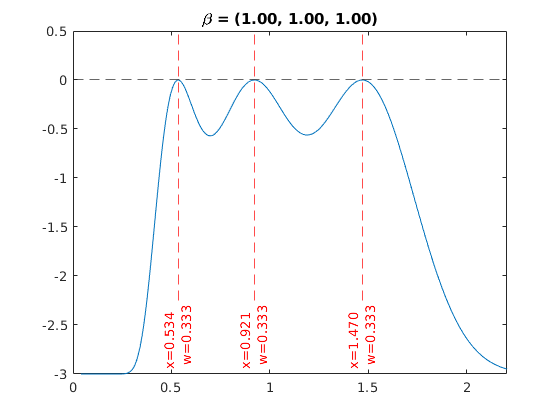

% simple case
beta = [1,1,1];
pts = 3;
sens = true;
int = [0, 100];

[obj, xi] = DoptFracPoly(beta, powers, pts, sens, algo, int);

GA on 1-objective 8-variable UserProblem (  1.00%), 0.05s passed...
GA on 1-objective 8-variable UserProblem (  2.00%), 0.09s passed...
GA on 1-objective 8-variable UserProblem (  3.00%), 0.14s passed...
GA on 1-objective 8-variable UserProblem (  4.00%), 0.17s passed...
GA on 1-objective 8-variable UserProblem (  5.00%), 0.21s passed...
GA on 1-objective 8-variable UserProblem (  6.00%), 0.24s passed...
GA on 1-objective 8-variable UserProblem (  7.00%), 0.28s passed...
GA on 1-objective 8-variable UserProblem (  8.00%), 0.32s passed...
GA on 1-objective 8-variable UserProblem (  9.00%), 0.35s passed...
GA on 1-objective 8-variable UserProblem ( 10.00%), 0.39s passed...
GA on 1-objective 8-variable UserProblem ( 11.00%), 0.42s passed...
GA on 1-objective 8-variable UserProblem ( 12.00%), 0.46s passed...
GA on 1-objective 8-variable UserProblem ( 13.00%), 0.49s passed...
GA on 1-objective 8-variable UserProblem ( 14.00%), 0.53s passed...
GA on 1-objective 8-variable UserProblem ( 15.00

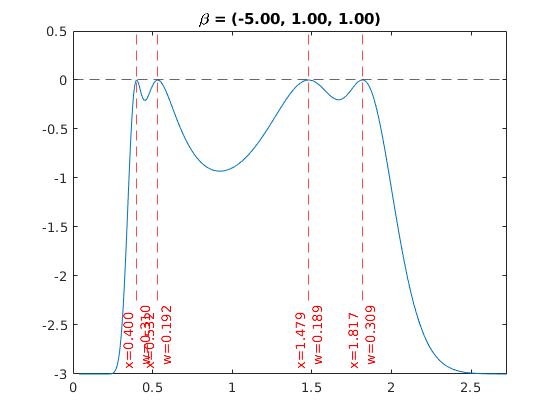

% some coefficients lead to a 4 point design
beta = [-5,1,1];
pts = 4;
[obj, xi] = DoptFracPoly(beta, powers, pts, sens, algo, int);

GA on 1-objective 6-variable UserProblem (  1.00%), 0.04s passed...
GA on 1-objective 6-variable UserProblem (  2.00%), 0.08s passed...
GA on 1-objective 6-variable UserProblem (  3.00%), 0.12s passed...
GA on 1-objective 6-variable UserProblem (  4.00%), 0.16s passed...
GA on 1-objective 6-variable UserProblem (  5.00%), 0.20s passed...
GA on 1-objective 6-variable UserProblem (  6.00%), 0.23s passed...
GA on 1-objective 6-variable UserProblem (  7.00%), 0.26s passed...
GA on 1-objective 6-variable UserProblem (  8.00%), 0.30s passed...
GA on 1-objective 6-variable UserProblem (  9.00%), 0.33s passed...
GA on 1-objective 6-variable UserProblem ( 10.00%), 0.36s passed...
GA on 1-objective 6-variable UserProblem ( 11.00%), 0.40s passed...
GA on 1-objective 6-variable UserProblem ( 12.00%), 0.43s passed...
GA on 1-objective 6-variable UserProblem ( 13.00%), 0.46s passed...
GA on 1-objective 6-variable UserProblem ( 14.00%), 0.50s passed...
GA on 1-objective 6-variable UserProblem ( 15.00

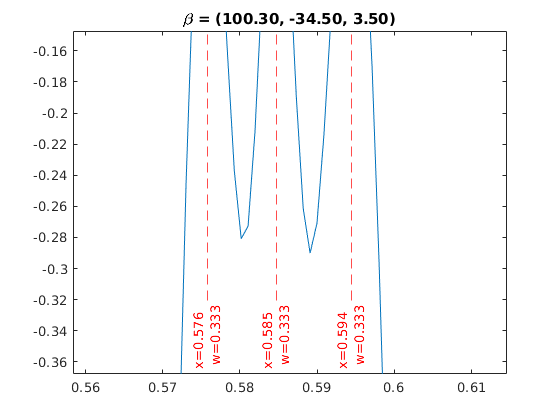


beta = [100.3, -34.5, 3.5];
pts = 3;
[obj, xi] = DoptFracPoly(beta, powers, pts, sens, algo, int);